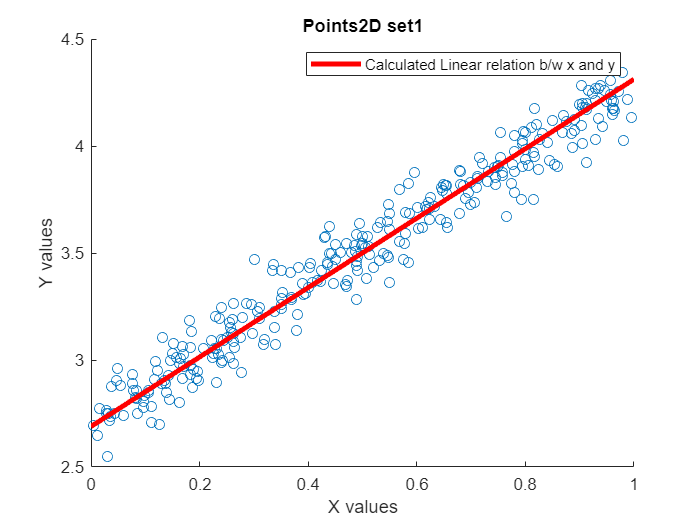

%Loading the first dataset
load('../../data/points2D_set1.mat');
data_matrix(1,:) = x'; %Populating the first row of the data_matrix with x values
data_matrix(2,:) = y'; %Populating the second row of the data_matrix with y values
[count, ~] = size(x); %Getting the number of points in count
mean_vector = sum(data_matrix,2)/count; %Finding the mean vector
mean_matrix = ones(2,count); %Mean matrix i.e. each column is the mean vector
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix)')/(count-1); %Calculating the covariance matrix
H = (data_matrix-mean_matrix)/sqrt(count-1); %Defining H matrix so as to calculate eigen vectors using H*H' which gives only real values
[V,D] = eig(H*H'); %Calculating this way because other ways might give complex eigen vectors due to numerical errors 
[d,ind] = sort(abs(diag(D)),'descend'); %Getting the sorted eigenvalues
principle_eigenval= d(1,1); %Finding the principle eigenvalue
principle_eigenvector = V(:,ind(1,1)); %Finding the principle eigenvector
scatter(x,y); %Making the scatter plot of the points 
x = linspace(0,1,1000); %Defining the linearspace on which the line will be drawn
slope = principle_eigenvector(2,1)/principle_eigenvector(1,1); %Finding the slope of the line given by the principle eigenvector
c = mean_vector(2,1) - slope*mean_vector(1,1); %Finding out the value of the y-intercept by making the line pass through mean value
y = slope.*x + c; %Equation of the line 
hold on
plot(x,y,'r-',LineWidth=3) %Plotting the line over the scatter plot
xlabel 'X values'
ylabel 'Y values'
title 'Points2D set1'
legend('','Calculated Linear relation b/w x and y')
hold off

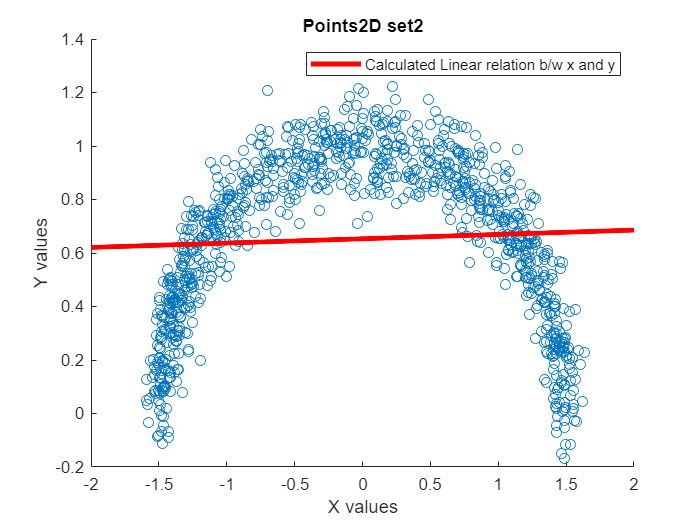

clear

%Doing the same with the second data sets

load('../../data/points2D_set2.mat');
data_matrix(1,:) = x';
data_matrix(2,:) = y';
[count, ~] = size(x);
mean_vector = sum(data_matrix,2)/count;
mean_matrix = ones(2,count);
    for i = 1:count
        mean_matrix(:,i) = mean_vector;
    end
cov_matrix = (data_matrix-mean_matrix)*((data_matrix-mean_matrix)')/(count-1);
H = (data_matrix-mean_matrix)/sqrt(count-1);
[V,D] = eig(H*H');
[d,ind] = sort(abs(diag(D)),'descend');
principle_eigenval= d(1,1);
principle_eigenvector = V(:,ind(1,1));
scatter(x,y);
x = linspace(-2,2,1000);
slope = principle_eigenvector(2,1)/principle_eigenvector(1,1);
c = mean_vector(2,1) - slope*mean_vector(1,1);
y = slope.*x + c;
hold on
plot(x,y,'r-',LineWidth=3)
xlabel 'X values'
ylabel 'Y values'
title 'Points2D set2'
legend('','Calculated Linear relation b/w x and y')
hold off

clear


